clear
M = readmatrix("计数数据20221105_194650.csv");
ch1 = M(3:3690,3);
ch2 = M(3:890,6);
ch = ch1;
%histogram(ch);

Nbar = mean(ch)  %平均值

Nbar = 4.9536

sigma = sqrt(Nbar)  %均方根

sigma = 2.2257

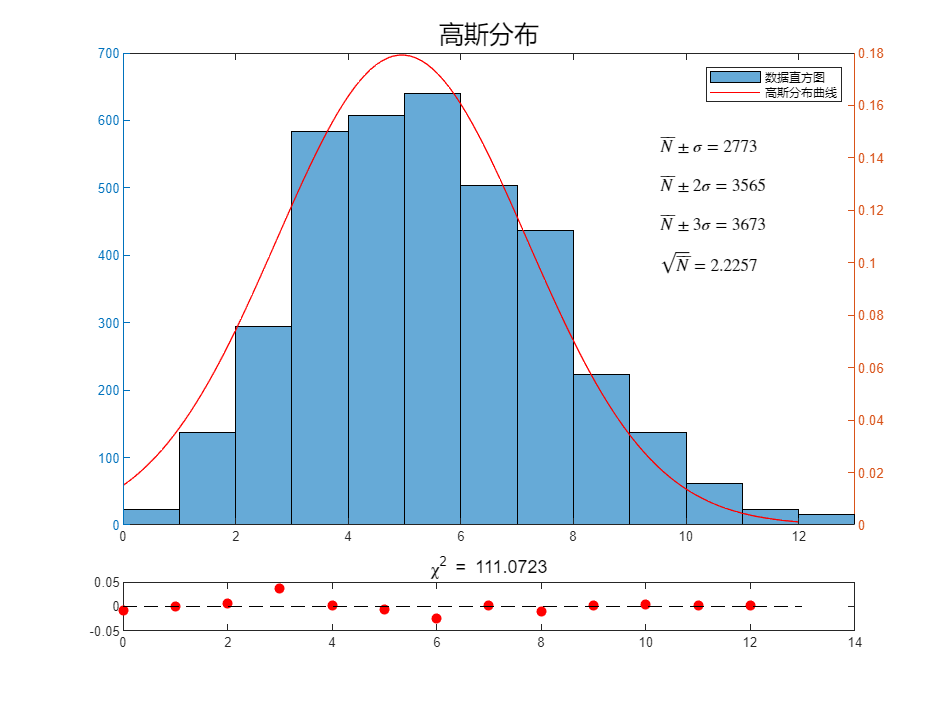


tiledlayout('flow','TileSpacing','compact')

g1 = nexttile([5 6]);  %柱状图和曲线图
set(gcf,'Units','centimeter','Position',[0 0 20 15]);
%hold on

N = 0:0.1:max(ch) - 1;
W = 1/(sqrt(2*pi)*sigma)*exp(-1*(N - Nbar).^2/(2*Nbar));  %Gaussian分布

yyaxis left
h = histogram(ch);
h.BinEdges = 0:max(ch);
yyaxis right
plot(N,W,'r-')
xlim([0 max(ch)])
title('高斯分布','FontSize',15)
legend('数据直方图','高斯分布曲线')

sig1 = sum(h.Values(1,ceil(Nbar-sigma) + 1:floor(Nbar+sigma) + 1));
sig2 = sum(h.Values(1,ceil(Nbar-2*sigma) + 1:floor(Nbar+2*sigma) + 1));
sig3 = sum(h.Values(1,1:floor(Nbar+3*sigma) + 1));

sig1 = ['$\overline N\pm\sigma = ', num2str(sig1), '$'];
sig2 = ['$\overline N\pm2\sigma = ', num2str(sig2), '$'];
sig3 = ['$\overline N\pm3\sigma = ', num2str(sig3), '$'];
Nb = ['$\sqrt{\overline N} = ',num2str(sigma),'$'];

text(9.5,0.145,sig1,'Interpreter','latex','FontSize',10)
text(9.5,0.13,sig2,'Interpreter','latex','FontSize',10)
text(9.5,0.115,sig3,'Interpreter','latex','FontSize',10)
text(9.5,0.1,Nb,'Interpreter','latex','FontSize',10)
%hold off

g2 = nexttile([1 6]);  %散点图
NN = 0:max(ch) - 1;
frac = h.Values./sum(h.Values);
WW = 1/(sqrt(2*pi)*sigma)*exp(-1*(NN - Nbar).^2/(2*Nbar));
ff = frac - WW;  %单次统计误差
chi1 = (h.Values - sum(h.Values).*WW).^2;
chi2 = sum(h.Values).*WW;
chi = chi1./chi2;
sum(chi);  %Chisq
hold on
box on
scatter(NN, ff,'red','filled')
%scatter(NN,chi1,'blue +')
plot([0 max(ch)],[0 0],'k --')
ylim([-0.05 0.05])
title(['\chi^2 = ',num2str(sum(chi))],'FontSize',11)